# **LECTURES on NETWORK SYSTEMS **

Based on: F. Bullo, Lectures on Network Systems, ed. 1.4, Kindle Direct Publishing, 2019, ISBN 978- 1986425643, with contributions by J. Cortés, F. Dörfler, and S. Martínez

## OPINION DYNAMICS *French-Harary-DeGroot Model* 


$$\mathbf{p}^{+}=A\mathbf{p}$$


$A$ is row stochastic.

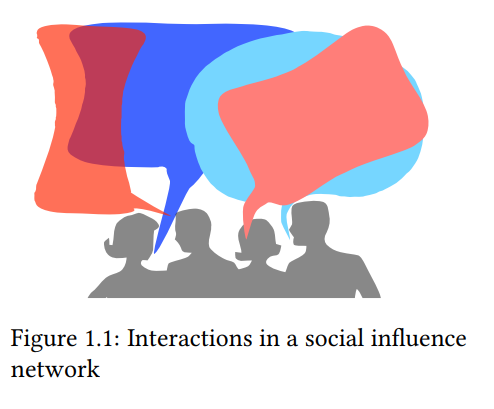

clc; clear; close all
%Initial conditions p0
N = 3

N = 3

pp = rand(1,N); p0 = [pp; 1 - pp];
p0 = p0(:);
p = p0;
% Subjective Distributions
a1 = [0.5, 0.4, 0.1];
a2 = [0.0, 0.8, 0.2];
a3 = [0.0, 0.0, 1];
A = [a1(1), 0, a1(2), 0, a1(3), 0; 0, a1(1), 0, a1(2) , 0, a1(3); a2(1), 0.0, a2(2), 0.0, a2(3), 0.0;...
    0.0, a2(1), 0.0, a2(2), 0.0, a2(3); a3(1), 0.0, a3(2), 0.0, a3(3), 0; 0.0, a3(1), 0.0, a3(2), 0.0 , a3(3)]

A =     0.5000         0    0.4000         0    0.1000         0
         0    0.5000         0    0.4000         0    0.1000
         0         0    0.8000         0    0.2000         0
         0         0         0    0.8000         0    0.2000
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000


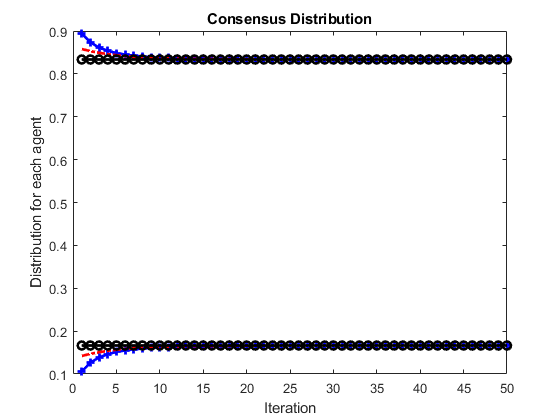

iter = 50;
for k = 2:iter
    p(:,k) = A*p(:,k-1);
end
plot(1:iter,p(1,:),'b-+',1:iter,p(2,:),'b-+',1:iter,p(3,:),'r-.',1:iter,p(4,:),'r-.',...
    1:iter,p(5,:),'k-o',1:iter,p(6,:),'k-o','LineWidth',2)
title('Consensus Distribution')
xlabel('Iteration')
ylabel('Distribution for each agent')

final_p =p(:,end)  % Consensus Agreement

final_p =     0.1665
    0.8335
    0.1665
    0.8335
    0.1665
    0.8335


initial_p = p(:,1)

initial_p =     0.1057
    0.8943
    0.1420
    0.8580
    0.1665
    0.8335


## n-bugs system - Cyclic Pursuit and Balancing

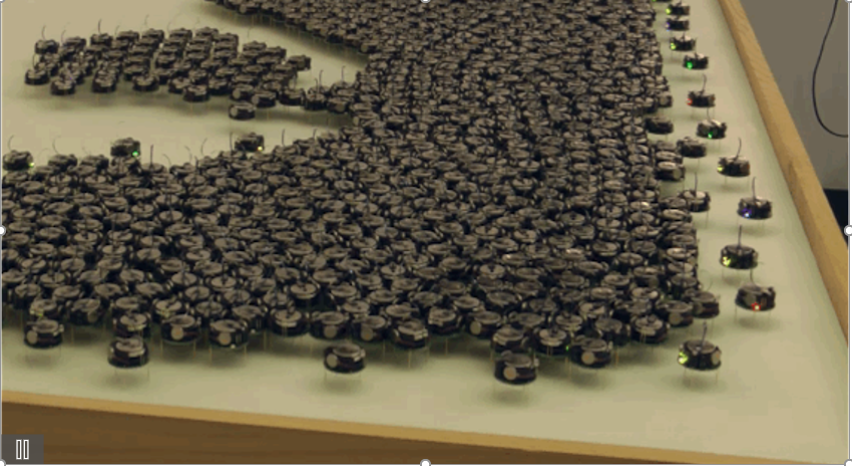

$\theta_{i}(k + 1) = mod(\theta_{i}(k) + u_{i}(k),2\pi)$ for each agent. Changing  angles to distances considering the new control laws

$u_{pursuit,i}(k) = \kappa d_{i}$ Cyclic Pursuit

$u_{balancing,i}(k)=\kappa d_{i} - \kappa d_{i-1}$ Balancing

$\kappa \in [0,1/2]$ balancing case

$\kappa \in [0,1]$ pursuit case

$d_{i}(k+1) = (1-\kappa)d_{i}(k) + \kappa d_{i+1}(k)$ Cyclic Pursuit

$d_{i}(k+1) = \kappa d_{i+1}(k) + (1-2\kappa)d_{i}(k) + \kappa d_{i-1}(k)$ Balancing

%% Cyclic Pursuit - Balancing
N = 4; %number of bugs
%Initial condition for distance of the i-th agent 
x0 = rand(N,1);
x = x0;
kappa = 0.1

kappa = 0.1000

% Closed-Loop  for Cyclic Pursuit 
A_pur = [1-kappa, kappa, 0.0, 0.0 ; 0.0, 1-kappa, kappa, 0.0; 0.0, 0.0, 1 - kappa, kappa;...
    kappa, 0.0, 0.0, 1 - kappa]

A_pur =     0.9000    0.1000         0         0
         0    0.9000    0.1000         0
         0         0    0.9000    0.1000
    0.1000         0         0    0.9000


% Closed-Loop  for Balancing
A_balancing = [1-2*kappa, kappa, 0.0, kappa; kappa, 1-2*kappa, kappa, 0.0; 0, kappa, 1 - 2*kappa, kappa;...
    kappa, 0.0, kappa, 1-2*kappa]

A_balancing =     0.8000    0.1000         0    0.1000
    0.1000    0.8000    0.1000         0
         0    0.1000    0.8000    0.1000
    0.1000         0    0.1000    0.8000


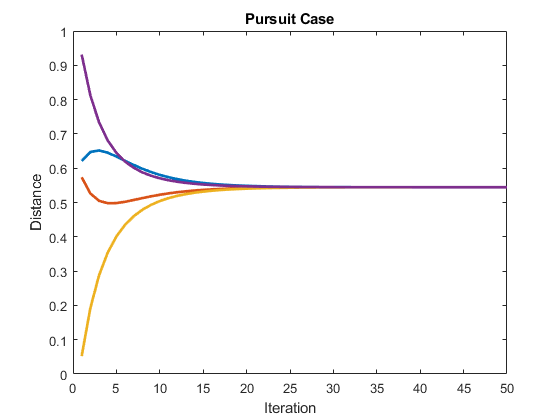

iter = 50;
for k = 2:iter
%       x(:,k) = A_pur*x(:,k-1);
    x(:,k) = A_balancing*x(:,k-1);
end
plot(1:iter,x(:,:),'LineWidth',2)
title('Pursuit Case')
xlabel('Iteration')
ylabel('Distance')

# **DISTRIBUTED CONTROL   - FUNDAMENTALS**

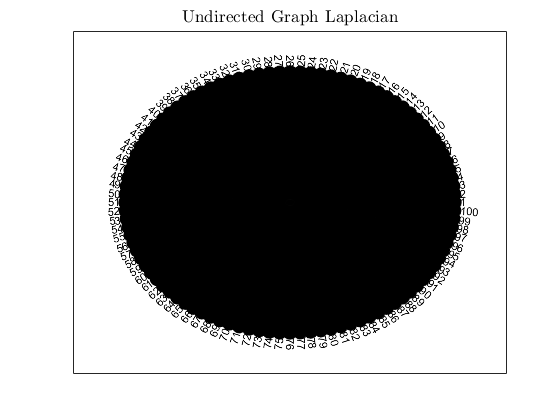

% Consensus
N = 100; %number of agents
T = toeplitz([0 ones(1,N-1)]); %Fully-connected graph, Unweighted Graph
% Gr = digraph(adj_mat); %directed graph
% For loop used to build the  Adjacency Matrix based upon a Toeplitz Matrix
for j = 1:length(T)
    T(j,j) = sum(T(j,:)) -  T(j,j);
    for k = 1:length(T)
        if j ~= k 
        T(j,k) = (-1)*T(j,k);
        end
    end
end
Degmat = diag(diag(T)); %Degree Matrix
Adjmat = T - Degmat;  %Adjacency Matrix
Adjmat = -Adjmat;
Gr = graph(Adjmat);
figure
plot(Gr,'k','LineWidth',1,'Layout','circle','MarkerSize',10);
title('Undirected Graph Laplacian','FontUnits','points','FontWeight','normal','FontSize',13,'FontName','Times',...
        'interpreter','latex')


% Distributed Protocol - Consensus
L = Degmat - Adjmat;
x = [];
dx = @(t,x) -L*x 

dx = function_handle with value:
    @(t,x)-L*x


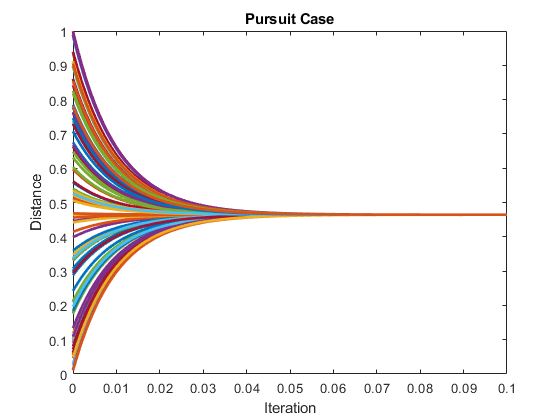

t=0:.001:0.1;
x00 = rand(1,N)';
[t,x]=ode45(@(t,x) dx(t,x),t,x00);
plot(t,x(:,:),'LineWidth',2)
title('Pursuit Case')
xlabel('Iteration')
ylabel('Distance')